# Chapter 22: Semidefinite Programming in Action

close all; clear all;

One considers here the optimization program

$\underset{f \in \mathcal{T}_n^{\rm even}}{\rm minimize} \; \|f^{(k)}\|_{L_p(\mathbb{T})}
\quad \mbox{subject to }
f(x^{(i)}) = y_i, \; i = 1,\ldots,m$.

Writing $ f \in \mathcal{T}_n^{\rm even}$ as $f = \sum_{j=0}^n a_j \cos(j \cdot) $, this program can be transformed into a semidefinite program involving $a \in \mathbb{R}^{n+1}$ in the cases $p=2$, $p=\infty$, and $p=1$, These cases are investigated below.

% generate the data
m = 15;
x = linspace(-pi,0,m);
y = (x.^2)';
% the matrix M used to express the equality constraints
n = 50;
M = zeros(m,n+1);
for j=0:n
        M(:,j+1) = cos(j*x);
end
% the grid necessary for plotting purposes
grid_size = 1000;
grid = linspace(-pi,pi,grid_size)';

## The case $p=2$

When $p=2$, the optimization program is transformed (using the Schur complement) into the following semidefinite program:


$$\underset{a \in \mathbb{R}^{n+1}, c\in \mathbb{R}}{\rm minimize} \; c
\quad \mbox{subject to }
Ma=y, \; \left[\matrix{c I_{n+1} & Da \cr (Da)^\top& c}\right] \succeq 0,$$


where $D \in \mathbb{R}^{(n+1) \times (n+1)}$is the diagonal matrix $D = \sqrt{\pi} {\rm diag}[0;1;\ldots;n^k]$.

% solving the SDP
k = 2;
D = sqrt(pi)*diag((0:n).^k);
cvx_begin quiet
variable a_2(n+1)
variable c
minimize c
subject to
M*a_2 == y;
[c*eye(n+1), D*a_2; (D*a_2)', c] == semidefinite(n+2)
cvx_end

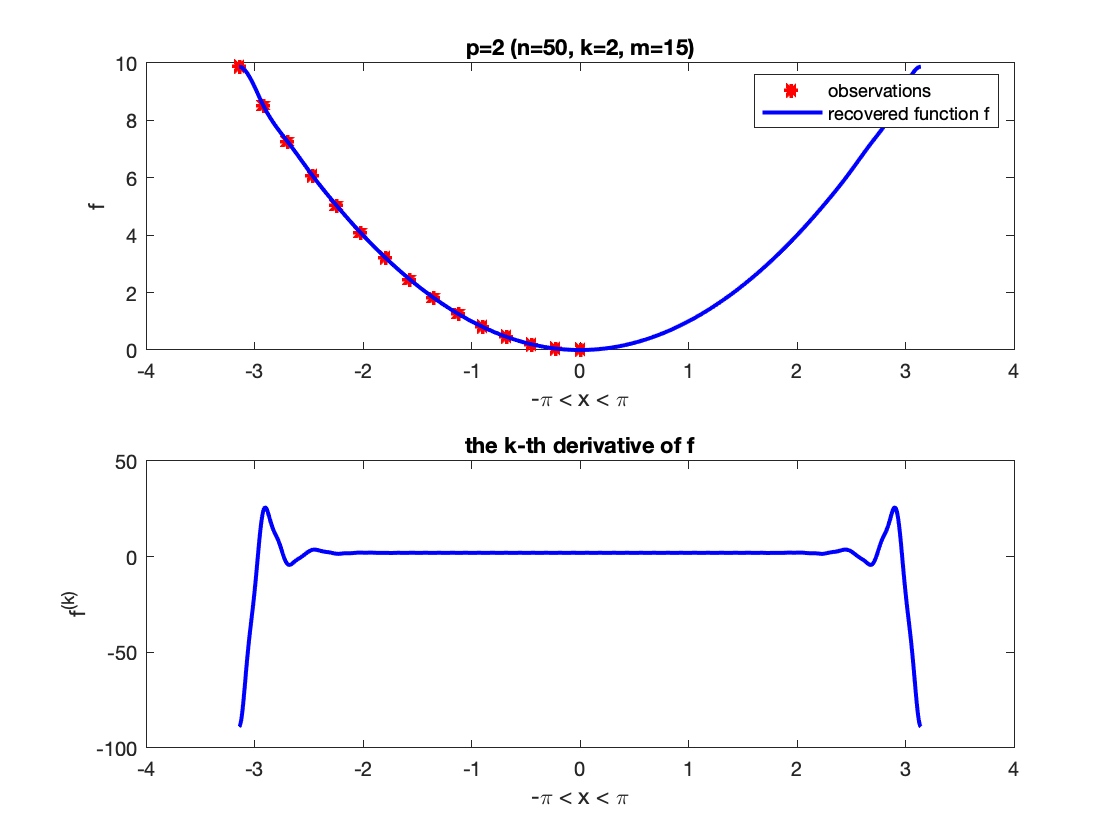

% visualizing the recovered function
f_2 = zeros(grid_size,1);
fk_2 = zeros(grid_size,1);
for j=0:n
    f_2 = f_2 + a_2(j+1)*cos(j*grid);
    fk_2 = fk_2 - a_2(j+1)*j^k*cos(j*grid);          % to be modified for a different k
end
subplot(2,1,1);
plot(x,y,'r*',grid,f_2,'b-','LineWidth',2)
legend('observations','recovered function f')
title(strcat('p=2 (n=',num2str(n),', k=',num2str(k),', m=',num2str(m),')'))
xlabel('-\pi < x < \pi') 
ylabel('f')
subplot(2,1,2);
plot(grid,fk_2,'b-','LineWidth',2)
title('the k-th derivative of f')
xlabel('-\pi < x < \pi') 
ylabel('f^{(k)}')

#### An aside: verification of the closed-form expression given in Exercise 22.1.

Delta = diag((1:n).^k);
A = M(:,2:end)/Delta;
B = inv(A*A');
a_sharp_0 = sum(y'.*sum(B))/sum(sum(B));
a_sharp = [a_sharp_0; Delta\( A'*B*(y-a_sharp_0) )];
fprintf(['The solution of the SDP and the closed-form expression agree: '...
    'the L2-distance between the coefficient vectors is %.1s'],norm(a_2-a_sharp))

The solution of the SDP and the closed-form expression agree: the L2-distance between the coefficient vectors is 3.0e-09

## The case $p=\infty$

When $p=\infty$ and $k \equiv 2 ({\rm mod}\, 4)$, the optimization program is transformed (using the sum-of-squares technique) into the following semidefinite program:


$$\underset{\matrix{a \in \mathbb{R}^{n+1},c \in \mathbb{R} \cr Q^+,Q^- \in \mathbb{C}^{(n+1) \times (n+1)}}}{\rm minimize} \, c
\qquad \mbox{subject to }
Ma = y, \; Q^{\pm } \succeq 0, \; \sum_i Q^{\pm}_{i,i}=c, \; \sum_{i-j=\ell} Q^{\pm}_{i,j} = \pm \frac{a_\ell \ell^k}{2} \mbox{ for }\ell =1,\ldots,n.$$


% solving the SDP
k = 2;                               % as before
cvx_begin quiet
variable a_inf(n+1)
variable c
variable Qp(n+1,n+1) semidefinite
variable Qm(n+1,n+1) semidefinite
expression up(n) 
expression um(n)
expression rhs(n)
for l=1:n
    up(l) = sum(diag(Qp,-l));
    um(l) = sum(diag(Qm,-l));
    rhs(l) = a_inf(j+1)*l^k/2;                          % to be modified for a different k
end
minimize c
subject to
M*a_inf == y;
trace(Qp) == c
trace(Qm) == c
up == +rhs
um == -rhs
cvx_end

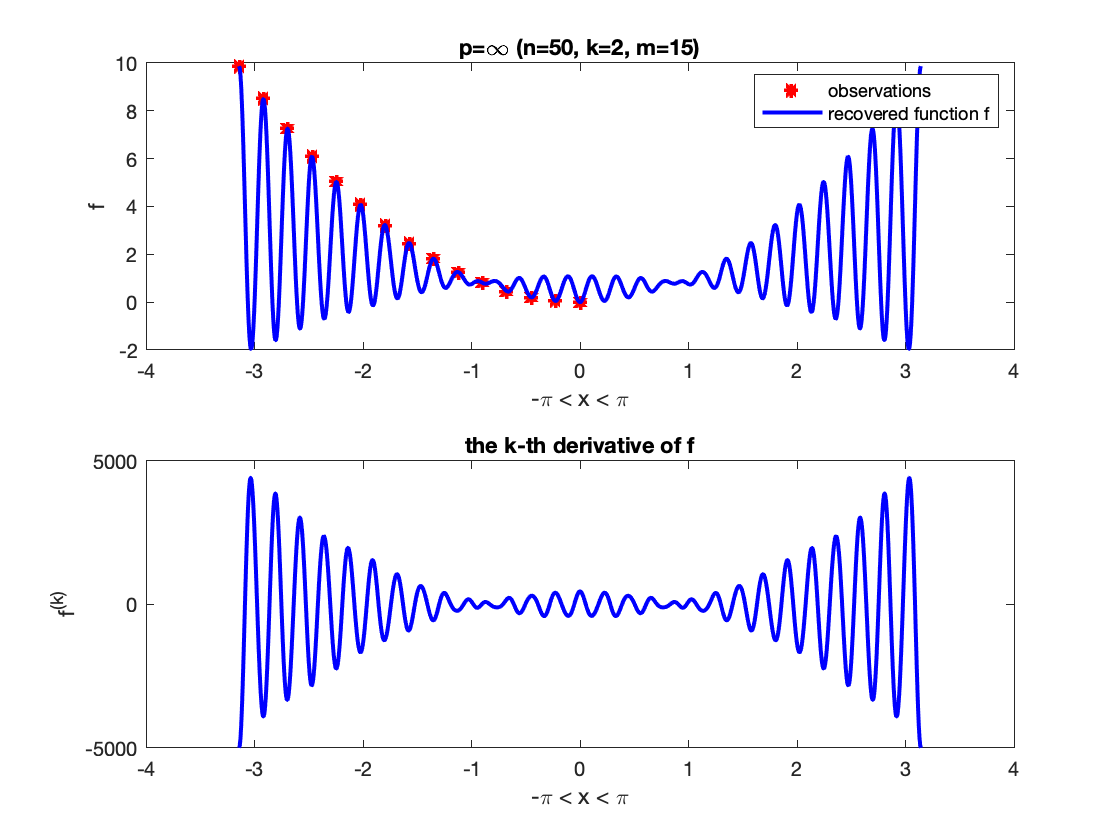

% visualizing the recovered function
f_inf = zeros(grid_size,1);
fk_inf = zeros(grid_size,1);
for j=0:n
    f_inf = f_inf + a_inf(j+1)*cos(j*grid);
    fk_inf = fk_inf - a_inf(j+1)*j^k*cos(j*grid);       % to be modified for a different k
end
subplot(2,1,1);
plot(x,y,'r*',grid,f_inf,'b-','LineWidth',2)
legend('observations','recovered function f')
title(strcat('p=\infty (n=',num2str(n),', k=',num2str(k),', m=',num2str(m),')'))
xlabel('-\pi < x < \pi') 
ylabel('f')
subplot(2,1,2);
plot(grid,fk_inf,'b-','LineWidth',2)
title('the k-th derivative of f')
xlabel('-\pi < x < \pi') 
ylabel('f^{(k)}')

## The case $p=1$

When $p=1$ and $k
$ is even, the optimization program is approximated (using the method of moments) by the following semidefinite program:


$$\underset{\matrix{a \in \mathbb{R}^{n+1}\cr u^+,u^- \in \mathbb{R}^{N+1}}}{\rm mininize}
(u^+_0 + u^-_0)
\quad \mbox{subject to }
Ma=y,\; {\rm Toep}_{N+1}(u^{\pm}) \succeq 0, \;
u^+ - u^- = \pi [0;a_1;a_2 2^k; \ldots; a_n n^k; 0 ; \ldots; 0],$$


where the truncation parameter $N \ge n$ is an integer chosen by the user (the bigger, the better, as long as the resulting SDP is solved efficiently and reliably).

% solving the SDP
k = 2;                 % as before
N = 100;
cvx_begin quiet
variable a_1(n+1)
variable up(N+1)
variable um(N+1)
expression rhs(N+1)
for j=1:N+1
    if j <= n+1
        rhs(j) = a_1(j)*(j-1)^k;
    else
        rhs(j) =0;
    end
end
minimize up(1)+um(1)
subject to
M*a_1 == y;
toeplitz(up) == semidefinite(N+1)
toeplitz(um) == semidefinite(N+1)
up - um == pi*rhs
cvx_end

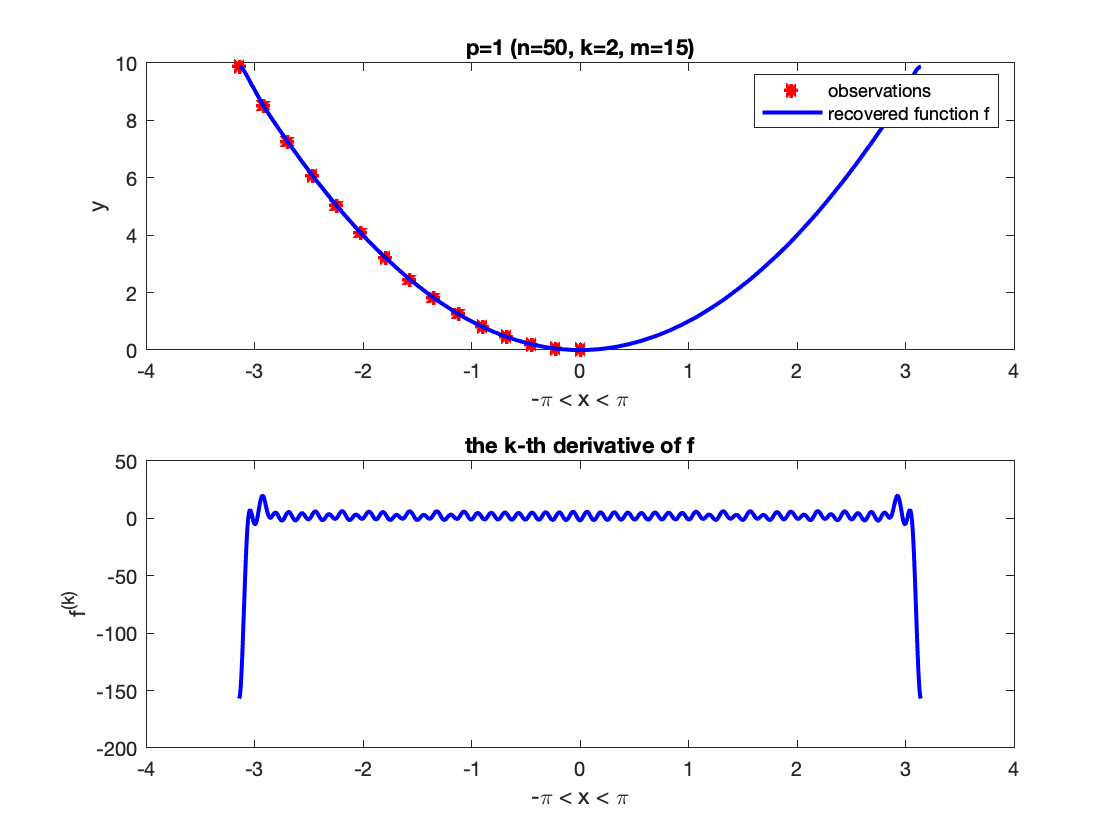

% visualizing the recovered function
f_1 = zeros(grid_size,1);
fk_1 = zeros(grid_size,1);
for j=0:n
    f_1 = f_1 + a_1(j+1)*cos(j*grid);
    fk_1 = fk_1 - a_1(j+1)*j^k*cos(j*grid);        % to be modified for a different k
end
subplot(2,1,1);
plot(x,y,'r*',grid,f_1,'b-','LineWidth',2)
legend('observations','recovered function f')
title(strcat('p=1 (n=',num2str(n),', k=',num2str(k),', m=',num2str(m),')'))
xlabel('-\pi < x < \pi') 
ylabel('y')
subplot(2,1,2);
plot(grid,fk_1,'b-','LineWidth',2)
title('the k-th derivative of f')
xlabel('-\pi < x < \pi') 
ylabel('f^{(k)}')